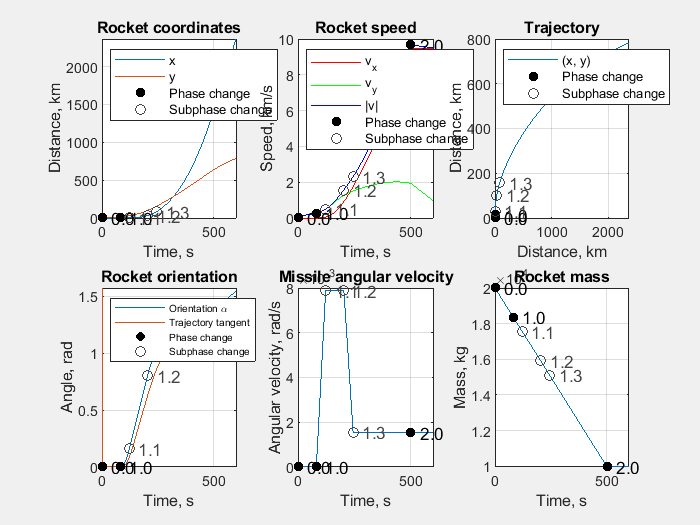

clear variables;
opengl software;

global u_range;
global F M;
global state;
global log;

u_range = struct();
u_range.m = 1;
u_range.r = 2:3;
u_range.v = 4:5;
u_range.alpha = 6;
u_range.omega = 7;
u_range.size = [7, 1];

F = struct();
M = struct();
state = struct();

log.state = table();
log.phases = table();
log.F = table();
log.M = table();

u0 = zeros(u_range.size);
u0(u_range.m) = 20e3;

options = odeset( ...
    'MaxStep', 1, ...
    'Refine', 1, ...
    'OutputFcn', @rocket_stepFinishedFcn ...
    );

state.phase = 0;
state.phaseStart = 0;
state.subPhase = 0;
state.supPhaseStart = 0;
state.phaseStarted = false;

rocket_controlFcn(0, u0);

[t, u] = ode45( ...
    @rocket_physFcn, ...
    [0 600], ...
    u0, ...
    options ...
    );

m = u(:, u_range.m);
r = u(:, u_range.r);
v = u(:, u_range.v);
alpha = u(:, u_range.alpha);
omega = u(:, u_range.omega);

x = r(:, 1);
y = r(:, 2);
vx = v(:, 1);
vy = v(:, 2);
tang = pi/2 - atan2(vy, vx);
v_norm = sqrt(vx.^2 + vy.^2);

N = length(t);


% Визуализация
myfigure('Solution: Shutov');

subplot(2, 3, 1);
plot(t, r(:, 1)/1000, 'DisplayName', 'x');
hold on;
plot(t, r(:, 2)/1000, 'DisplayName', 'y');
plotChangePhasePoints(t, [t, x/1000]);

title('Rocket coordinates');
xlabel('Time, s');
ylabel('Distance, km');
legend("Location", 'northwest');
grid on;

subplot(2, 3, 2);
plot(t, v(:, 1)/1000, 'r', 'DisplayName', 'v_x');
hold on;
plot(t, v(:, 2)/1000, 'g', 'DisplayName', 'v_y');
hold on;
plot(t, v_norm/1000, 'b', 'DisplayName', '|v|');
hold on;
plotChangePhasePoints(t, [t, v_norm/1000]);
title('Rocket speed');
xlabel('Time, s');
ylabel('Speed, km/s');
legend("Location", 'northwest');
grid on;

subplot(2, 3, 3);
plot(r(:, 1)/1000, r(:, 2)/1000, 'DisplayName', '(x, y)');
hold on;
plotChangePhasePoints(t, [r(:, 1)/1000, r(:, 2)/1000]);
title('Trajectory');
xlabel('Distance, km');
ylabel('Distance, km');
legend('Location', 'northwest');
grid on;

subplot(2, 3, 4);
plot(t, alpha, "DisplayName", 'Orientation \alpha');
hold on;
plot(t, tang, "DisplayName", 'Trajectory tangent');
plotChangePhasePoints(t, [t, alpha]);
title('Rocket orientation');
xlabel('Time, s');
ylabel('Angle, rad');
lgd = legend('Location', 'northwest');
lgd.FontSize = 6;
grid on;

subplot(2, 3, 5);
plot(t, omega);
plotChangePhasePoints(t, [t, omega]);
title('Missile angular velocity');
xlabel('Time, s');
ylabel('Angular velocity, rad/s');
grid on;

subplot(2, 3, 6);
plot(t, m);
plotChangePhasePoints(t, [t, m]);
title('Rocket mass');
xlabel('Time, s');
ylabel('Mass, kg');
grid on;

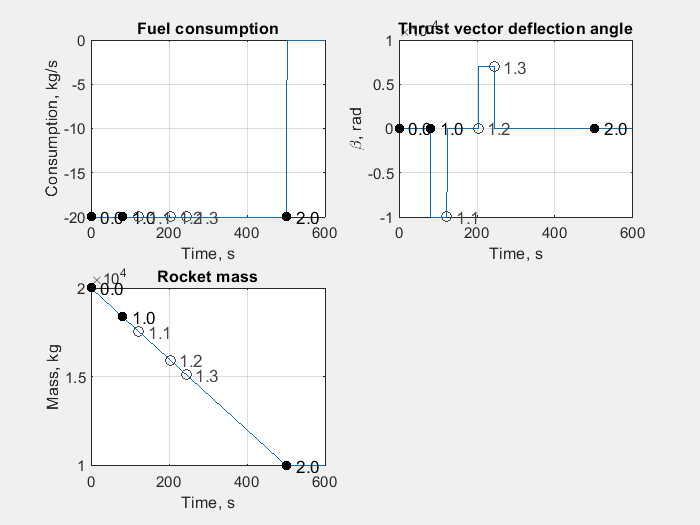


myfigure('Rocket parameters: Shutov');

subplot(221);
plot(t, log.state.massFlow);
plotChangePhasePoints(t, [t, log.state.massFlow]);
title('Fuel consumption');
xlabel('Time, s');
ylabel('Consumption, kg/s');
grid on;

subplot(222);
plot(t, log.state.beta);
plotChangePhasePoints(t, [t, log.state.beta]);
xlabel('Time, s');
ylabel('\beta, rad');
title('Thrust vector deflection angle');
grid on;

subplot(223);
plot(t, m);
plotChangePhasePoints(t, [t, m]);
title('Rocket mass');
xlabel('Time, s');
ylabel('Mass, kg');
grid on;

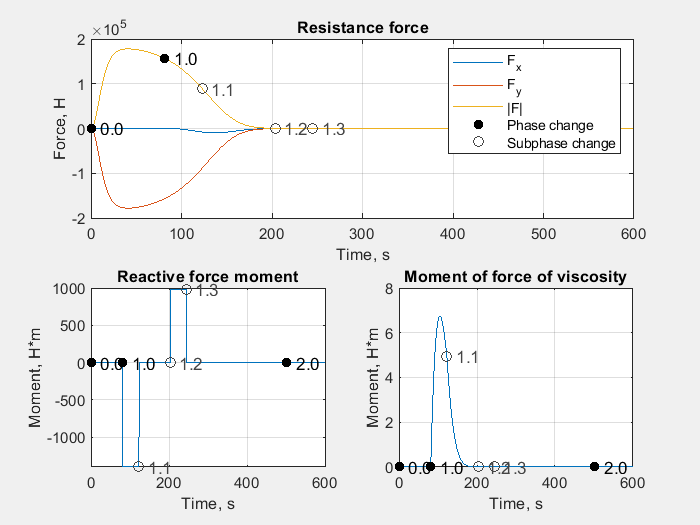




myfigure('Forces and moments: Shutov');

subplot(2, 2, [1, 2]);
plot(t, log.F.resist(:, 1), 'DisplayName', 'F_x');
hold on;
plot(t, log.F.resist(:, 2), 'DisplayName', 'F_y');

resist_norm = sqrt(log.F.resist(:, 1).^2 + log.F.resist(:, 2).^2);
plot(t, resist_norm,'DisplayName', '|F|');
plotChangePhasePoints(t, [t, resist_norm]);
grid on;
title('Resistance force');
xlabel('Time, s');
ylabel('Force, H');
legend();

subplot(223);
plot(t, log.M.jet);
plotChangePhasePoints(t, [t, log.M.jet]);
grid on;
title('Reactive force moment');
xlabel('Time, s');
ylabel('Moment, Н*m');

subplot(224);
plot(t, log.M.resist);
plotChangePhasePoints(t, [t, log.M.resist]);
grid on;
title('Moment of force of viscosity');
xlabel('Time, s');
ylabel('Moment, Н*m');

function f = myfigure(name, varargin)
    f = figure( ...
        'Visible', 'on', ...
        'NumberTitle', 'off', ...
        'Name', name, ...
        varargin{:} ...
        );
end

function plotChangePhasePoints(t, r1)
    global log;
    
    hold on;
    
    sz = size(log.phases.t);
    x = zeros(sz);
    y = zeros(sz);
    labels = cell(sz);
    descriptions = cell(sz);
    phaseChange = false(sz);
    
    for i = 1 : height(log.phases)
        j = find(t >= log.phases.t(i), 1);
        x(i) = r1(j, 1);
        y(i) = r1(j, 2);
        
        labels(i) = cellstr(['  ' num2str(log.phases.phase(i)) '.' num2str(log.phases.subPhase(i))]);
        descriptions(i) = log.phases.description(i);
        
        phaseChange(i) = log.phases.subPhase(i) == 0;
    end
    
    subPhaseChange = ~phaseChange;
    
    text(x(phaseChange), y(phaseChange), labels(phaseChange), 'FontSize', 10, 'Color', 'k');
    text(x(subPhaseChange), y(subPhaseChange), labels(subPhaseChange), 'FontSize', 10, 'Color', '#444444');
    
    p1 = plot(x(phaseChange), y(phaseChange), 'k.', "MarkerSize", 20, "DisplayName", 'Phase change');
    p2 = plot(x(subPhaseChange), y(subPhaseChange), 'o', 'Color', '#444444',"DisplayName", 'Subphase change');
    
    row1 = dataTipTextRow('Phase', descriptions(phaseChange));
    row2 = dataTipTextRow('Subphase', descriptions(subPhaseChange));
    p1.DataTipTemplate.DataTipRows(end + 1) = row1;
    p2.DataTipTemplate.DataTipRows(end + 1) = row2;
end